# Electrodes

Copyright (C) 2022 Miodrag Bolic

 This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

main_path=fileparts(which('Main_Content.mlx'));
if ~isempty(main_path)
    %addpath(append(main_path,'/Chapter2'))
    cd (append(main_path,'/Chapter2/Electrodes'))
    addpath(append(main_path,'/Service'))
end
SAVE_FLAG=0; % saving the figures in a file

## Introduction

In this notebook we will show different models of the electrodes as well as the interface between the skin and the electrodes.

## Connecting two wet electrodes

load('ecg.mat')
model_name = 'ConnectingWetElectrodes';
open_system(model_name);


%blockHandle = get_param('ConnectingWetElectrodes/ElectrodeSkinModel2/Rep', 'Handle')
%block = get(blockHandle);

Potential difference for the same electrodes and skin parameters

set_param('ConnectingWetElectrodes/ElectrodeSkinModel2/Rep','R','500')
set_param('ConnectingWetElectrodes/ElectrodeSkinModel1/Rep','R','500')
set_param('ConnectingWetElectrodes/Zero','Value','0')
s=sim(model_name)

s =   Simulink.SimulationOutput:

                 simout: [1x1 timeseries] 
                   tout: [100001x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


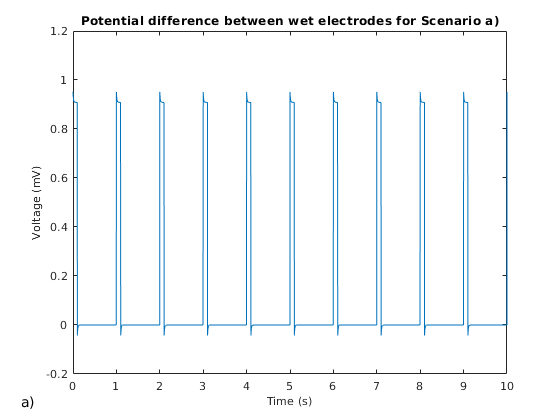

figure
plot(s.simout.Time, s.simout.Data*1000)
xlabel('Time (s)', 'FontSize', 10)
ylabel('Voltage (mV)', 'FontSize', 10)
ylim([-0.2, 1.2])
title("Potential difference between wet electrodes for Scenario a)")
annonation_save('a)',"Fig2.12a.jpg", SAVE_FLAG);

Potential difference for the same electrodes and skin parameters

Rep=get_param('ConnectingWetElectrodes/ElectrodeSkinModel2/Rep','R')

Rep = '500'

set_param('ConnectingWetElectrodes/ElectrodeSkinModel2/Rep','R','251')
s=sim(model_name)

s =   Simulink.SimulationOutput:

                 simout: [1x1 timeseries] 
                   tout: [100001x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


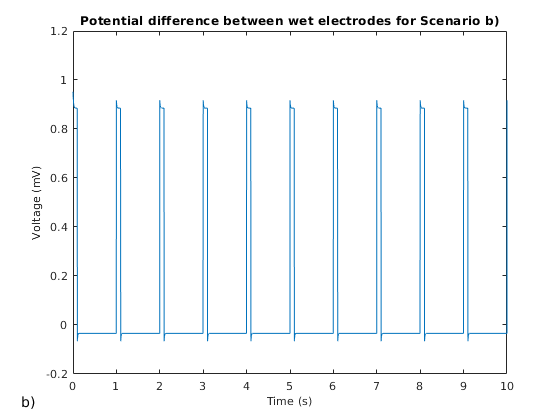

figure
plot(s.simout.Time, s.simout.Data*1000)
xlabel('Time (s)', 'FontSize', 10)
ylabel('Voltage (mV)', 'FontSize', 10)
ylim([-0.2, 1.2])
title("Potential difference between wet electrodes for Scenario b)")
annonation_save('b)',"Fig2.12b.jpg", SAVE_FLAG);

After skin abrasion, epidermal resistances are 5kOhm and 10kOhm

%Rep=get_param('ConnectingWetElectrodes/ElectrodeSkinModel2/Rep','R')
set_param('ConnectingWetElectrodes/ElectrodeSkinModel2/Rep','R','5')
set_param('ConnectingWetElectrodes/ElectrodeSkinModel1/Rep','R','10')
s=sim(model_name)

s =   Simulink.SimulationOutput:

                 simout: [1x1 timeseries] 
                   tout: [100001x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


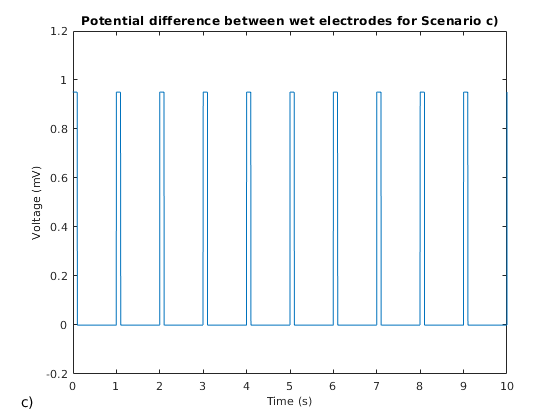

figure
plot(s.simout.Time, s.simout.Data*1000)
xlabel('Time (s)', 'FontSize', 10)
ylabel('Voltage (mV)', 'FontSize', 10)
ylim([-0.2, 1.2])
title("Potential difference between wet electrodes for Scenario c)")
annonation_save('c)',"Fig2.12c.jpg", SAVE_FLAG);

After turning on sweat:

%Rep=get_param('ConnectingWetElectrodes/ElectrodeSkinModel2/Rep','R')
set_param('ConnectingWetElectrodes/ElectrodeSkinModel2/Rep','R','500')
set_param('ConnectingWetElectrodes/ElectrodeSkinModel1/Rep','R','500')
set_param('ConnectingWetElectrodes/Zero','Value','1')
s=sim(model_name)

s =   Simulink.SimulationOutput:

                 simout: [1x1 timeseries] 
                   tout: [100001x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


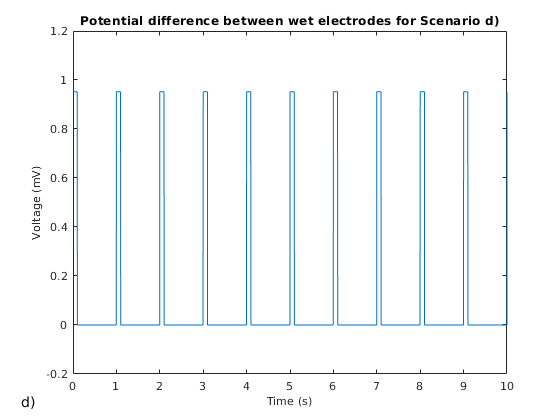

figure
plot(s.simout.Time, s.simout.Data*1000)
xlabel('Time (s)', 'FontSize', 10)
ylabel('Voltage (mV)', 'FontSize', 10)
ylim([-0.2, 1.2])
title("Potential difference between wet electrodes for Scenario d)")
annonation_save('d)',"Fig2.12d.jpg", SAVE_FLAG);

## Dry electrode

model_name = 'ConnectingDryElectrodes';
open_system(model_name);


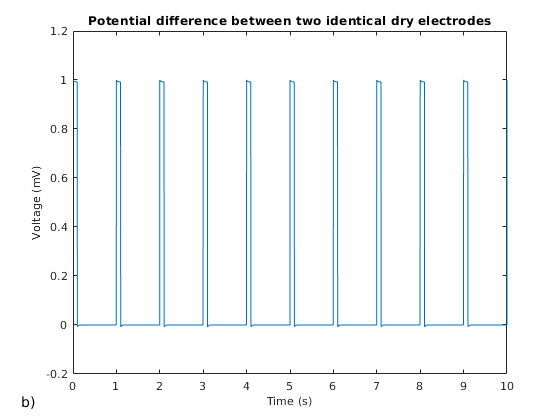


s=sim(model_name);
figure
plot(s.simout.Time, s.simout.Data*1000)
xlabel('Time (s)', 'FontSize', 10)
ylabel('Voltage (mV)', 'FontSize', 10)
ylim([-0.2, 1.2])
title("Potential difference between two identical dry electrodes")
annonation_save('b)',"Fig2.13b.jpg", SAVE_FLAG);

## Non-contact electrode

model_name = 'ConnectingNoContactElectrodes';
open_system(model_name);


Simulation with Rin=1GOhm

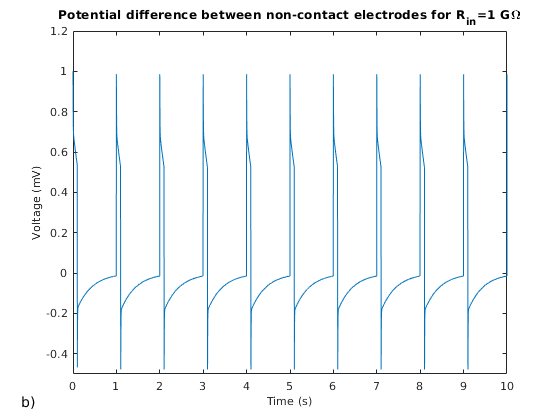

set_param('ConnectingNoContactElectrodes/Rin','R','1')
s=sim(model_name);
figure
plot(s.simout.Time, s.simout.Data*1000)
xlabel('Time (s)', 'FontSize', 10)
ylabel('Voltage (mV)', 'FontSize', 10)
ylim([-0.5, 1.2])
title("Potential difference between non-contact electrodes for R_{in}=1 G\Omega")
annonation_save('b)',"Fig2.14b.jpg", SAVE_FLAG);

Simulation with Rin=1GOhm

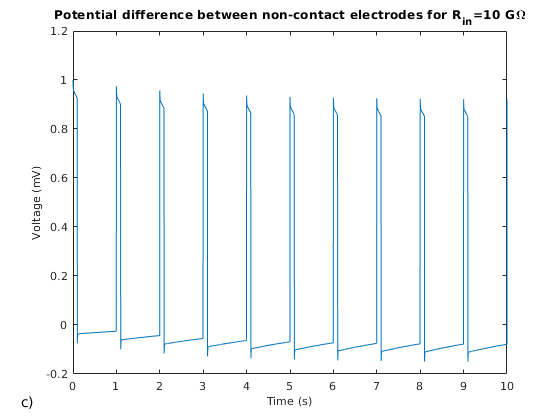

set_param('ConnectingNoContactElectrodes/Rin','R','10')
s=sim(model_name);
figure
plot(s.simout.Time, s.simout.Data*1000)
xlabel('Time (s)', 'FontSize', 10)
ylabel('Voltage (mV)', 'FontSize', 10)
ylim([-0.2, 1.2])
title("Potential difference between non-contact electrodes for R_{in}=10 G\Omega")
annonation_save('c)',"Fig2.14c.jpg", SAVE_FLAG);